# Tutorial04 Simulating and Imaging Randomly Diffusing Molecules

#### Notes

Note.

Save all my code. They will be reused and build on each other.

Objective: To be more famiiar with Matrix multiplications through a variation of a random walk.

2. Simulating a Random Walk in 1D

1.. Initialize two matrices

% Parameters
L = 500

L = 500

n_particle = 500

n_particle = 500

n_kicks = 10000

n_kicks = 10000


f = zeros(n_kicks, n_particle);
x = zeros(n_kicks, n_particle);

2.. Assign the initial particle positions in f(1, :) such that the n_p particles are uniformly disributed across the Universe.

% Initially did
% f(1,:) = length*rand(1, n_particle)

% After reaching step 5, for convenience, decided to refer to the solution.
f(1,:) = randperm(L)

f =    120    84   365   127    32   218   130   298   162   297   191   124   146   477   248   427    90   444   212    99     5   240   100   107   140   202   207   161   390   483   470   337   386    56   360   183   389   278   363   244    81   263   345   190   423   138   173   373   460    20
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   

3.. Store displacement of each kick.

Received help from solution doc.

% Assign kicks at each time step.
f(2:end,:) = randn(n_kicks-1, n_particle)

f =   120.0000   84.0000  365.0000  127.0000   32.0000  218.0000  130.0000  298.0000  162.0000  297.0000  191.0000  124.0000  146.0000  477.0000  248.0000  427.0000   90.0000  444.0000  212.0000   99.0000    5.0000  240.0000  100.0000  107.0000  140.0000  202.0000  207.0000  161.0000  390.0000  483.0000  470.0000  337.0000  386.0000   56.0000  360.0000  183.0000  389.0000  278.0000  363.0000  244.0000   81.0000  263.0000  345.0000  190.0000  423.0000  138.0000  173.0000  373.0000  460.0000   20.0000
   -0.4942   -0.8893   -0.5980   -0.3354    1.2992    0.6166    0.0606   -0.6995    0.3286   -0.2591   -1.9295   -0.1671    1.0356   -1.1482    1.2070   -0.6256   -2.5298    0.5823    0.4492   -1.2316    0.7113   -0.1878    0.8597    1.4393   -0.5546   -1.6627   -0.0310   -2.5771    1.5417    0.0977    0.8505   -0.8724   -0.9293    0.6890    0.6259    0.5479   -0.7128   -0.0534    0.7165   -2.0114   -0.0098    0.3753    1.6755    1.5443    0.0733    0.2035   -0.5203   -0.1775    0.3724   -1

Note. Difference between **rand** and **randn**.

**rand**: uniformly distributed random numbers. Returns random #s between 0 and 1 from uniform distribution.

**randn**: normally(Gaussian) distributed random numbers. Returns random #s of mean 0 and variance 1.

4.. Assign x to the particle trajectories. Use **cumsum** and mod.

% help cumsum
% stepx = cumsum(-1+2*stepx)
x = cumsum(f)

x =   120.0000   84.0000  365.0000  127.0000   32.0000  218.0000  130.0000  298.0000  162.0000  297.0000  191.0000  124.0000  146.0000  477.0000  248.0000  427.0000   90.0000  444.0000  212.0000   99.0000    5.0000  240.0000  100.0000  107.0000  140.0000  202.0000  207.0000  161.0000  390.0000  483.0000  470.0000  337.0000  386.0000   56.0000  360.0000  183.0000  389.0000  278.0000  363.0000  244.0000   81.0000  263.0000  345.0000  190.0000  423.0000  138.0000  173.0000  373.0000  460.0000   20.0000
  119.5058   83.1107  364.4020  126.6646   33.2992  218.6166  130.0606  297.3005  162.3286  296.7409  189.0705  123.8329  147.0356  475.8518  249.2070  426.3744   87.4702  444.5823  212.4492   97.7684    5.7113  239.8122  100.8597  108.4393  139.4454  200.3373  206.9690  158.4229  391.5417  483.0977  470.8505  336.1276  385.0707   56.6890  360.6259  183.5479  388.2872  277.9466  363.7165  241.9886   80.9902  263.3753  346.6755  191.5443  423.0733  138.2035  172.4797  372.8225  460.3724   18

x = mod(x, 500)

x =   120.0000   84.0000  365.0000  127.0000   32.0000  218.0000  130.0000  298.0000  162.0000  297.0000  191.0000  124.0000  146.0000  477.0000  248.0000  427.0000   90.0000  444.0000  212.0000   99.0000    5.0000  240.0000  100.0000  107.0000  140.0000  202.0000  207.0000  161.0000  390.0000  483.0000  470.0000  337.0000  386.0000   56.0000  360.0000  183.0000  389.0000  278.0000  363.0000  244.0000   81.0000  263.0000  345.0000  190.0000  423.0000  138.0000  173.0000  373.0000  460.0000   20.0000
  119.5058   83.1107  364.4020  126.6646   33.2992  218.6166  130.0606  297.3005  162.3286  296.7409  189.0705  123.8329  147.0356  475.8518  249.2070  426.3744   87.4702  444.5823  212.4492   97.7684    5.7113  239.8122  100.8597  108.4393  139.4454  200.3373  206.9690  158.4229  391.5417  483.0977  470.8505  336.1276  385.0707   56.6890  360.6259  183.5479  388.2872  277.9466  363.7165  241.9886   80.9902  263.3753  346.6755  191.5443  423.0733  138.2035  172.4797  372.8225  460.3724   18

**cumsum**: cumulative sum of elements. Check documentation how it works for a matrix.

Sample Code

`Cumsum of each column`

`A = [1 4 7; 2 5 8; 3 6 9]`

`A = `*3×3*

`     1     4     7`

`     2     5     8`

`     3     6     9`

`B = cumsum(A)`

`B = ``3×3`

`     1     4     7`

`     3     9    15`

`     6    15    24`

`Cumsum of each row`

`A = [1 3 5; 2 4 6]`

`A = ``2×3`

`     1     3     5`

`     2     4     6`

`B = cumsum(A,2)`

`B = ``2×3`

`     1     4     9`

`     2     6    12`

**mod**: Takes mod. 

Sample code.

q = [0:10] 

mod(q,5)

mod(q,4)

Q = [0:10;0:10;0:10] 

mod(Q,5) 

mod(Q,2)

Here, mod is used to ensure the particles stay in the universe.

5.. Visualizing particle trajectories by creating an *image*.

I(x,t). corresponds to the # of particles at location x at time t. 

Image: a matrix that represents the grid of pixels, whose entires contain some info about those pixels - here, it's intensity. c.f. The higher the count of a pixel, the brighter it'll be.

% first, use ceiling to discretize x.
x = ceil(x)

x =    120    84   365   127    32   218   130   298   162   297   191   124   146   477   248   427    90   444   212    99     5   240   100   107   140   202   207   161   390   483   470   337   386    56   360   183   389   278   363   244    81   263   345   190   423   138   173   373   460    20
   120    84   365   127    34   219   131   298   163   297   190   124   148   476   250   427    88   445   213    98     6   240   101   109   140   201   207   159   392   484   471   337   386    57   361   184   389   278   364   242    81   264   347   192   424   139   173   373   461    19
   121    84   366   126    34   219   131   296   162   297   190   124   147   476   251   428    88   447   213    99     6   242   102   109   140   201   206   160   392   483   472   336   385    58   360   185   391   279   363   242    83   264   349   193   425   138   174   373   460    19
   122    85   365   124    35   220   130   296   162   297   189   123   148   477   251   


% create image to store result.
% initialize image
I = zeros(L, n_kicks)

I =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   


% for each number from 1 to 500, count the occurence and store in the matrix.
for n = 1:n_kicks
    % disp(n)
    location_ranges = 1:500;
    [counts, ind] = histc(x(n, :), location_ranges);
    % transpose(counts)
    I(:, n) = transpose(counts);  % can use " counts.' "
end

I

I =      1     0     0     1     1     1     1     2     0     2     2     0     1     0     2     2     2     1     0     1     0     0     0     1     0     2     1     0     0     1     1     0     1     1     0     1     1     1     1     0     1     2     1     2     0     1     0     1     1     2
     1     1     1     1     1     0     0     0     0     1     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     2     1     1     1     0     0     1     0     2     2     1     2     0     2     3     1     1     0     0     0     2     2
     1     1     0     0     0     0     0     0     0     0     1     1     0     1     1     0     0     0     1     0     1     1     1     1     1     0     2     2     1     1     2     0     2     1     0     2     0     1     2     1     2     0     0     1     1     2     0     1     0     0
     1     2     1     1     0     0     0     1     1     0     0     0     0     0     0   

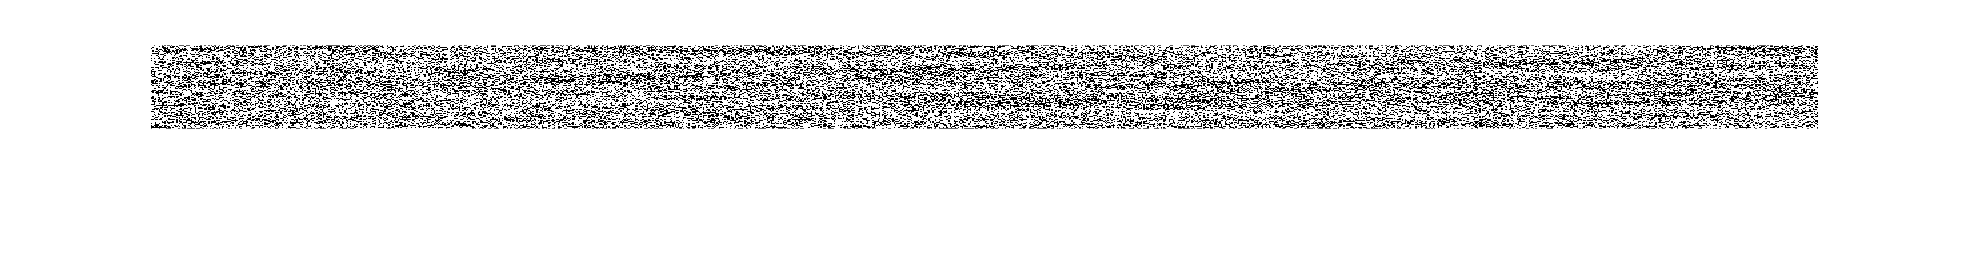

%groupcounts(x)

imshow(I)

Original image

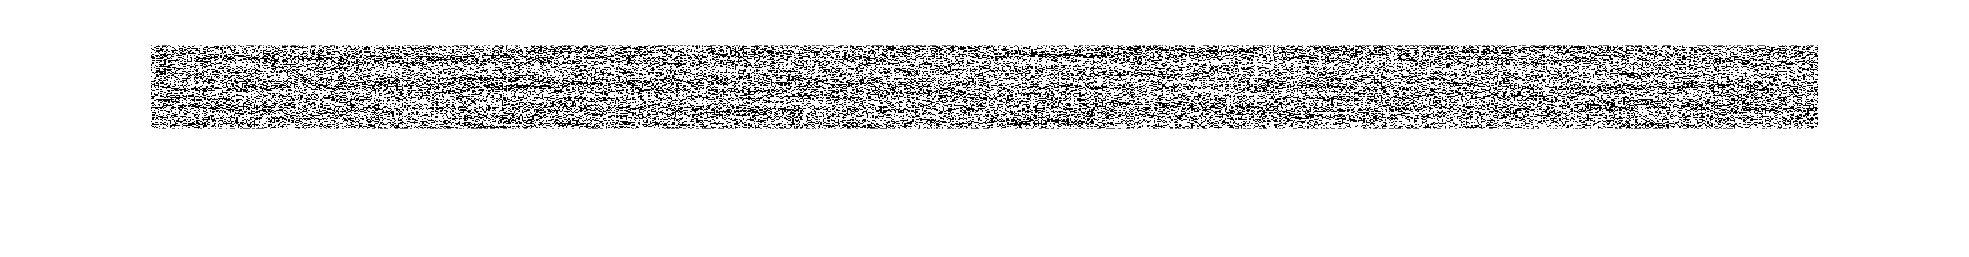

Choosing subsection of the matrix and showing it.

I_section = I(:, 3:950)

I_section =      0     1     1     1     1     2     0     2     2     0     1     0     2     2     2     1     0     1     0     0     0     1     0     2     1     0     0     1     1     0     1     1     0     1     1     1     1     0     1     2     1     2     0     1     0     1     1     2     0     3
     1     1     1     0     0     0     0     1     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     2     1     1     1     0     0     1     0     2     2     1     2     0     2     3     1     1     0     0     0     2     2     3     2
     0     0     0     0     0     0     0     0     1     1     0     1     1     0     0     0     1     0     1     1     1     1     1     0     2     2     1     1     2     0     2     1     0     2     0     1     2     1     2     0     0     1     1     2     0     1     0     0     1     1
     1     1     0     0     0     1     1     0     0     0     0     0     0     0 

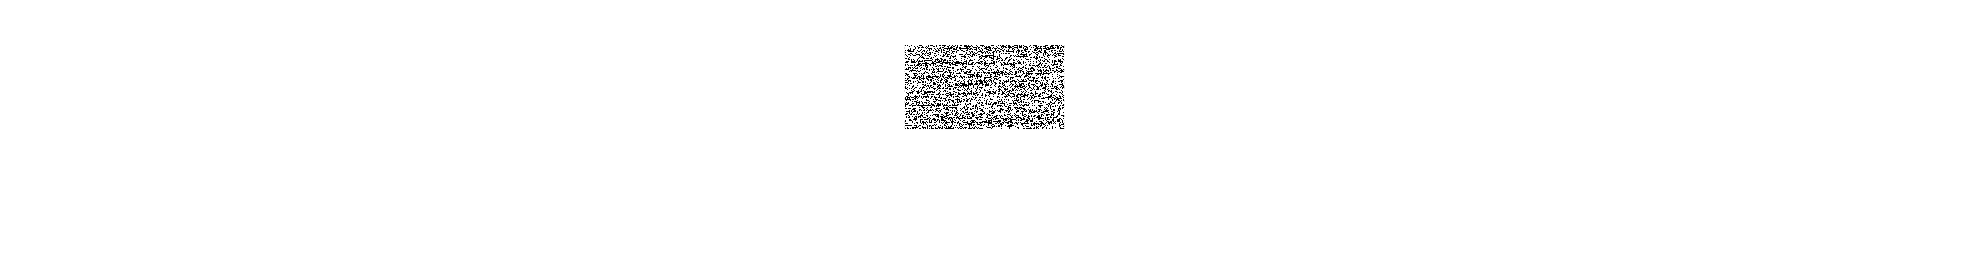

imshow(I_section)

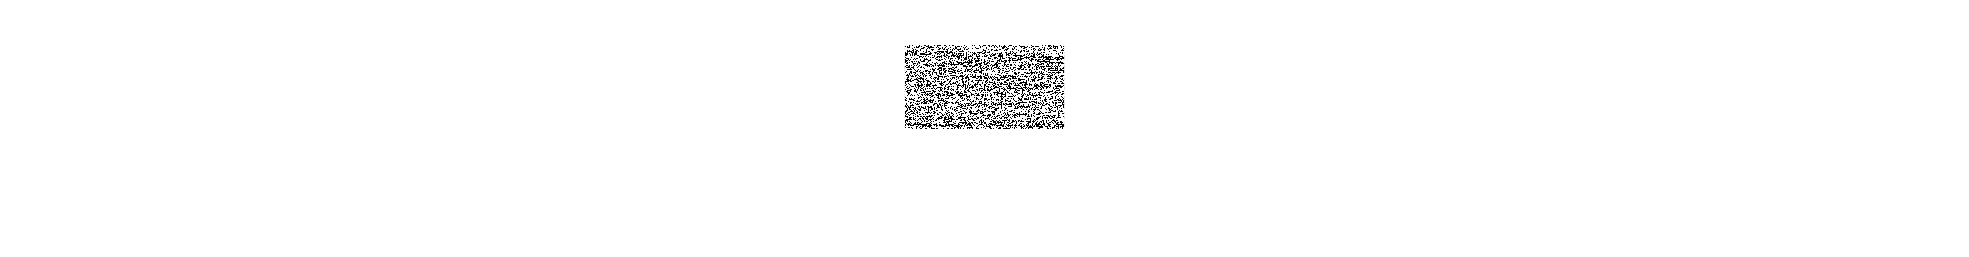

6.. Calculate the variance in positions sampled by each particle.

var_particles = var(transpose(I))

var_particles =     0.9572    0.9512    0.9587    0.9476    0.9629    0.9380    0.9075    0.9095    0.8922    0.9377    0.9412    0.9729    0.9732    0.9962    0.9822    0.9933    1.0424    1.0365    1.0231    1.0566    1.0405    1.0527    1.0374    1.0126    1.0326    0.9571    0.9816    0.9848    0.9238    0.9620    0.9732    1.0099    0.9707    0.9331    0.9450    0.9362    0.9338    0.9057    0.9263    0.9057    0.9022    0.9184    1.0150    0.9805    0.9560    0.9264    0.9623    0.9510    0.9707    0.9956



% Avg value for variance over all particles:
[temp, arrL] = size(var_particles)

temp = 1

arrL = 500

avg_variance = mean(sum(var_particles)) / arrL

avg_variance = 0.9928

The average value for variance over all particles, after a couple of runs of the program, was very close to 1: e.g. 0.9861, 0.9894, 0.9938. This IS what we expect, because the values are pretty much 1, and the kicks were Gaussian-distributed, which means it has variance 1.

7. Define the deffusion coefficient as D = var/(2*N_kicks). Calculate D.

D = avg_variance/(2*n_kicks)

D = 4.9642e-05

The output: `D = 4.9521e-05, D = 4.9422e-05`

`When I googled, I found:`

`"`In an aqueous (water) solution, typical diffusion **coefficients** are in the range of 10 -10 to 10 -9 m 2 /s`"`

`and,`

`"`A typical diffusion coefficient for a molecule in the gas phase is in the range of **10 -6 to 10 -5 m 2 /s**.`".`

`If we assume that the universe as in "gas phase", then it seems to be falling in the range 10^-6 to 10^-5.`

`8.. Calculate, approximately, how many pixels - h - will a protein molecule diffusion (in 2D) in a given camera exposure time of 2ms/frame.`

% 100um^2/s * (1 pixel/ 0.4um) * (2 ms / frame)
% 2ms = 2000
h = 100*(1/0.4)*2000

h = 500000

Answer: 500000 pixels.